# CT Exam 06/07/2023

Mikolaj Suchon 405821

Witold Surdej 407100

# Part A

%set up
format("short","g")
clear
clc

%defining constants:
km=5.7;
mF=0.8;
mM=1e-5;
mL=0.3;
dF=6; 
kF=6000;
db=1;
kb=800;
d=3;

TASK1

a)

%defining state matrices:
A=[-(db+d)/mL 0 d/mL 0 db/mL kb/mL;
      1    0      0   0   0      0;
      d/mF 0 -(dF+d)/mF kF/mF 0  0;
      0    0   -1         0   0  0;
      db/mM 0  0  0 -db/mM  -kb/mM;
      -1   0      0   1   0      0]

A =       -13.333            0           10            0       3.3333       2666.7
            1            0            0            0            0            0
         3.75            0       -11.25         7500            0            0
            0            0           -1            0            0            0
        1e+05            0            0            0       -1e+05       -8e+07
           -1            0            0            1            0            0



B=[0; 0; -km/mF; 0; km/mM; 0]

B =             0
            0
       -7.125
            0
      5.7e+05
            0



C=[0 1 0 0 0 0;
   0 0 0 1 0 0;
   0 0 0 0 0 1]

C =      0     1     0     0     0     0
     0     0     0     1     0     0
     0     0     0     0     0     1



D=[0; 0; 0]

D =      0
     0
     0


b)

%to get tf for out xload
[num1, den1]=ss2tf(A,B,C(1,:),D(1,:));
sys1=tf(num1, den1)

sys1 =
 
           1.9e06 s^3 + 1.425e07 s^2 + 1.425e10 s + 0.0002255
  --------------------------------------------------------------------
  s^6 + 1e05 s^5 + 2.135e06 s^4 + 7.576e08 s^3 + 7.52e09 s^2 + 1.099 s
 
Continuous-time transfer function.



%to get tf for out xframe
[num2, den2]=ss2tf(A,B,C(2,:),D(2,:));
sys2=tf(num2, den2)

sys2 =
 
    7.125 s^4 + 7.126e05 s^3 + 1.9e04 s^2 - 1.393e-06 s - 2.384e-24
  --------------------------------------------------------------------
  s^6 + 1e05 s^5 + 2.135e06 s^4 + 7.576e08 s^3 + 7.52e09 s^2 + 1.099 s
 
Continuous-time transfer function.



%to get tf for out xmotor
[num3, den3]=ss2tf(A,B,C(3,:),D(3,:));
sys3=tf(num3, den3)

sys3 =
 
          -1.9e06 s^3 - 1.354e07 s^2 - 1.425e10 s + 0.0005461
  --------------------------------------------------------------------
  s^6 + 1e05 s^5 + 2.135e06 s^4 + 7.576e08 s^3 + 7.52e09 s^2 + 1.099 s
 
Continuous-time transfer function.



c)

%getting poles of each system
P1=pole(sys1)

P1 =             0 +          0i
       -1e+05 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i
      -10.077 +          0i
  -1.4611e-10 +          0i


P2=pole(sys2)

P2 =             0 +          0i
       -1e+05 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i
      -10.077 +          0i
  -1.4611e-10 +          0i


P3=pole(sys3)

P3 =             0 +          0i
       -1e+05 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i
      -10.077 +          0i
  -1.4611e-10 +          0i


%getting eigenvalues for each system
e1=eig(sys1)

e1 =             0 +          0i
       -1e+05 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i
      -10.077 +          0i
  -1.4611e-10 +          0i


e2=eig(sys2)

e2 =             0 +          0i
       -1e+05 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i
      -10.077 +          0i
  -1.4611e-10 +          0i


e3=eig(sys3)

e3 =             0 +          0i
       -1e+05 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i
      -10.077 +          0i
  -1.4611e-10 +          0i


d)

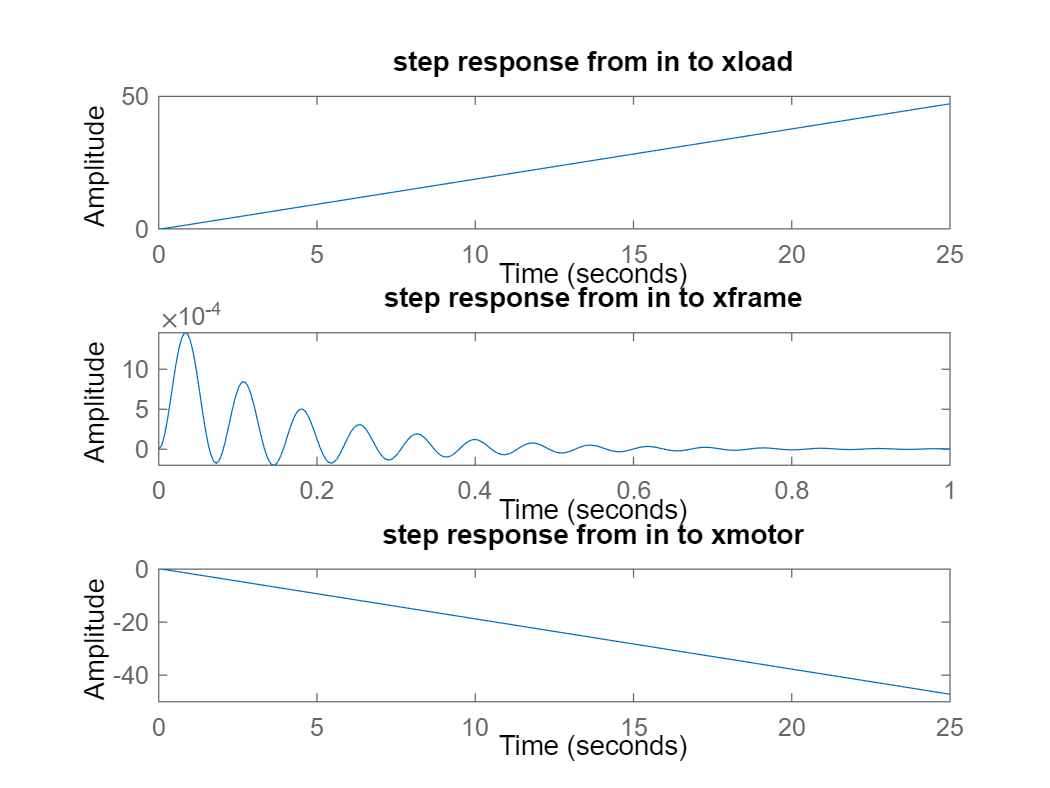

%plotting step responses for each system
figure()
subplot(3,1,1)
step(sys1)
title("step response from in to xload")
subplot(3,1,2)
step(sys2)
title("step response from in to xframe")
subplot(3,1,3)
step(sys3)
title("step response from in to xmotor")

Step response from in to xload implies unstable behaviour (goes to infinity). 

Step response from in to xframe behaves in a damped oscillatory manner (stable).

Step response from in to xmotor shows instability (goes to minus infinity).

e)

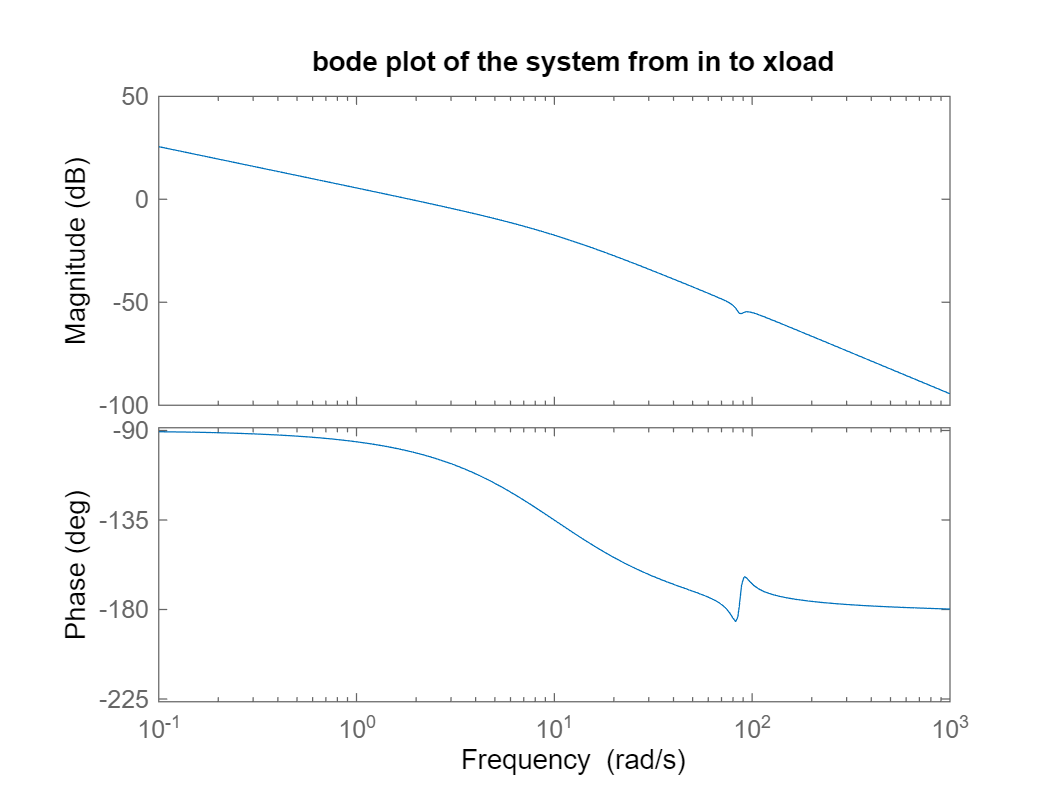

%plotting bode plots for each system
figure()
bode(sys1)
title("bode plot of the system from in to xload")

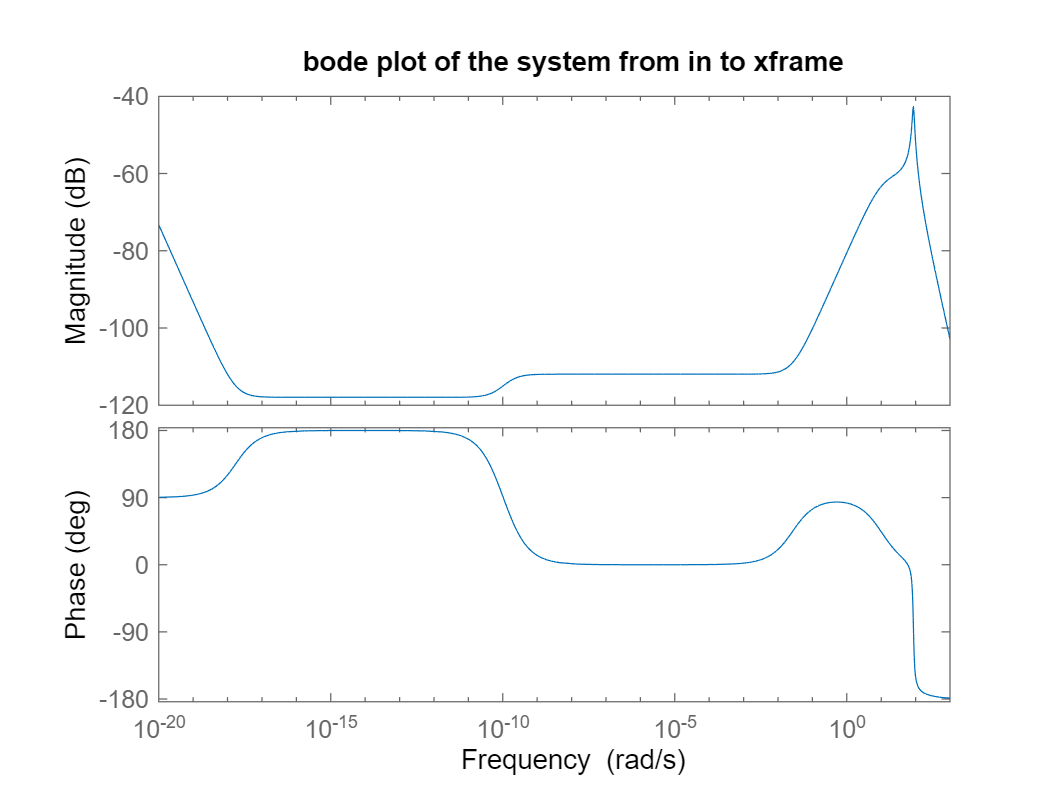

figure()
bode(sys2)
title("bode plot of the system from in to xframe")

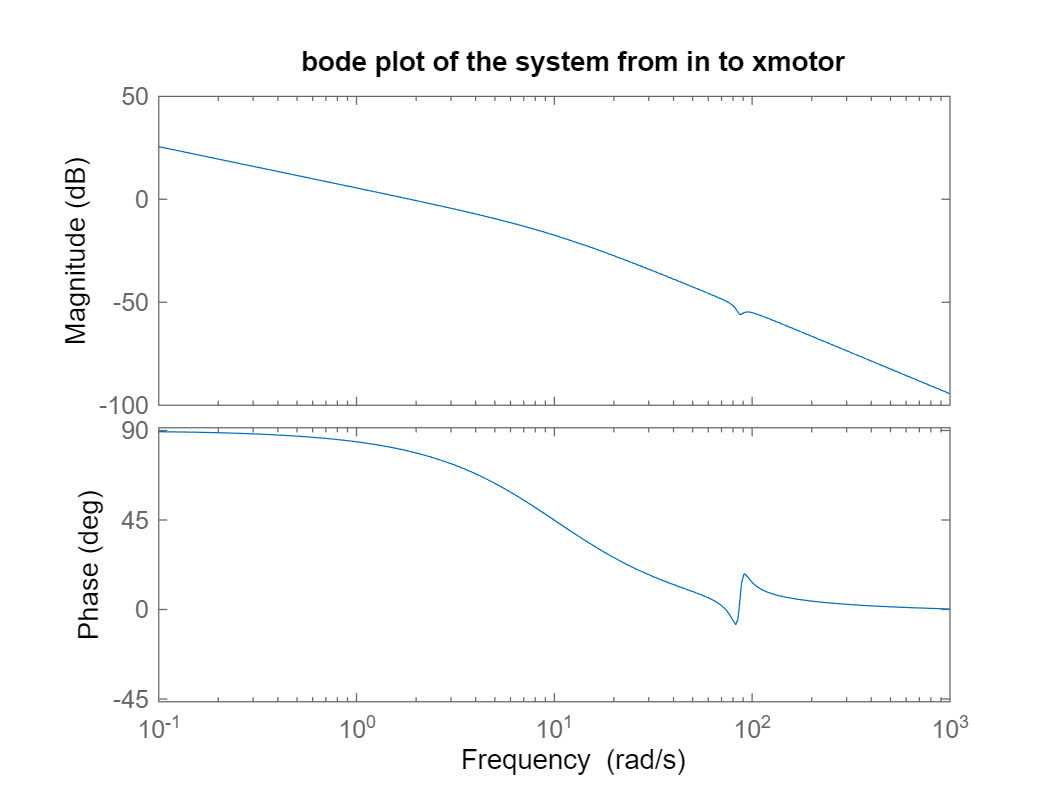

figure()
bode(sys3)
title("bode plot of the system from in to xmotor")

TASK2

a)

%checking controllability of the system
Cc=ctrb(A,B);
rank_of_Cc=rank(Cc)

rank_of_Cc =      1


controllability=length(A)-rank_of_Cc

controllability =      5


Given that the rank of the controllability matrix of the system is 1 while the order of the system is 6, the system has controllability deficiency of 5, therefore it is uncontrollable. 

%checking observability for each output
%xload
O1 = obsv(A, C(1,:));
rank_of_O_load = rank(O1) 

rank_of_O_load =      3


%xframe
O2 = obsv(A, C(2,:));
rank_of_O_frame = rank(O2) 

rank_of_O_frame =      3


%xmotor
O3 = obsv(A, C(3,:));
rank_of_O_motor = rank(O3) 

rank_of_O_motor =      3


The system is unobservable from the input to any of the outputs used, individual or combined. Beacouse the rank of the observability matrix for each of them is 3.

TASK3

%defining system
G6l=tf(num1, den1)

G6l =
 
           1.9e06 s^3 + 1.425e07 s^2 + 1.425e10 s + 0.0002255
  --------------------------------------------------------------------
  s^6 + 1e05 s^5 + 2.135e06 s^4 + 7.576e08 s^3 + 7.52e09 s^2 + 1.099 s
 
Continuous-time transfer function.



a)

%poles
P=pole(G6l)

P =             0 +          0i
       -1e+05 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i
      -10.077 +          0i
  -1.4611e-10 +          0i


%zeros
Z=zero(G6l)

Z =       -3.7501 +     86.523i
      -3.7501 -     86.523i
  -1.5827e-14 +          0i


Based on the poles of the 6th order linear system, it is marginally stable since all of the real values of the complex poles are in the left hand plane ie. negative except for one at 0.

b)

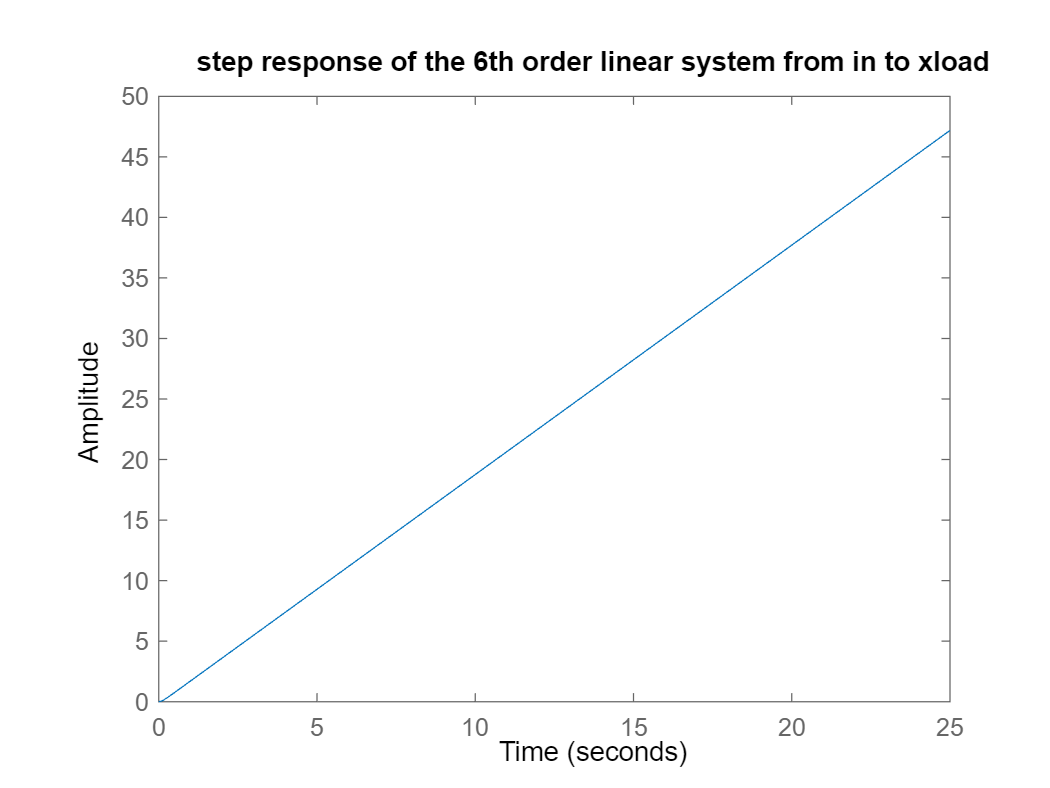

%plotting step and bode
figure()
step(G6l)
title("step response of the 6th order linear system from in to xload")

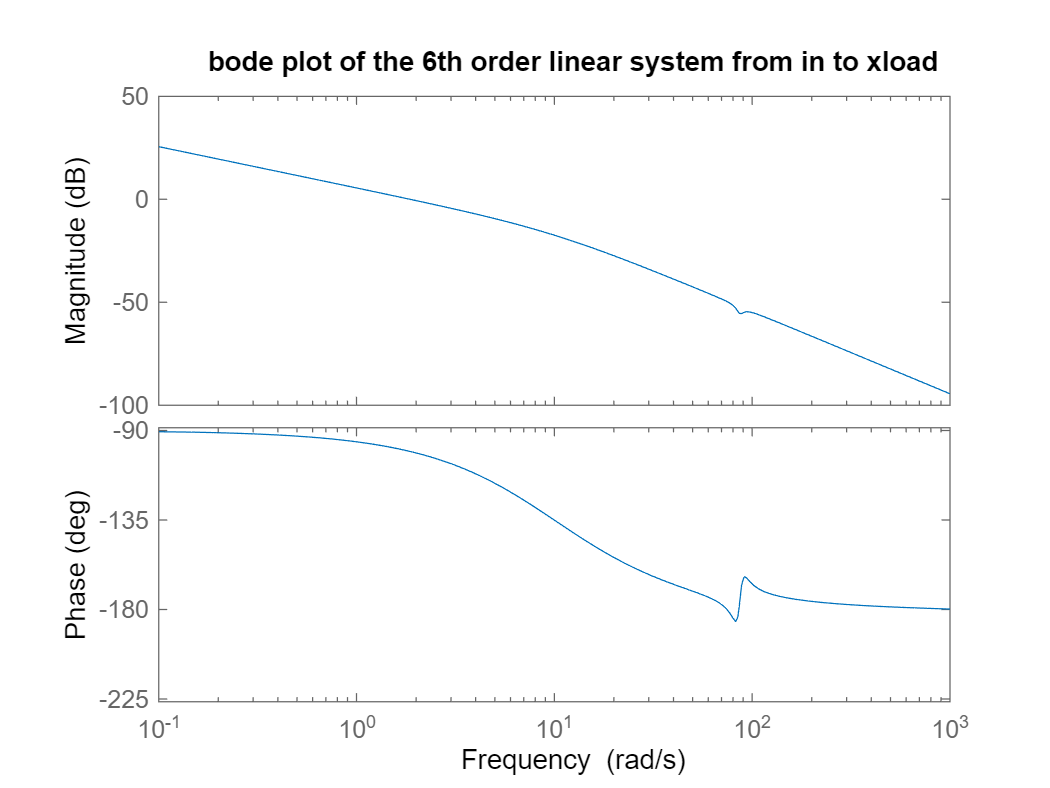

figure()
bode(G6l)
title("bode plot of the 6th order linear system from in to xload")

Step response of this system shows unstability (goes to infinity)

From Bode plot we conclude that the open loop system is unstable due to unsatisfied phase margin criterion.

c)

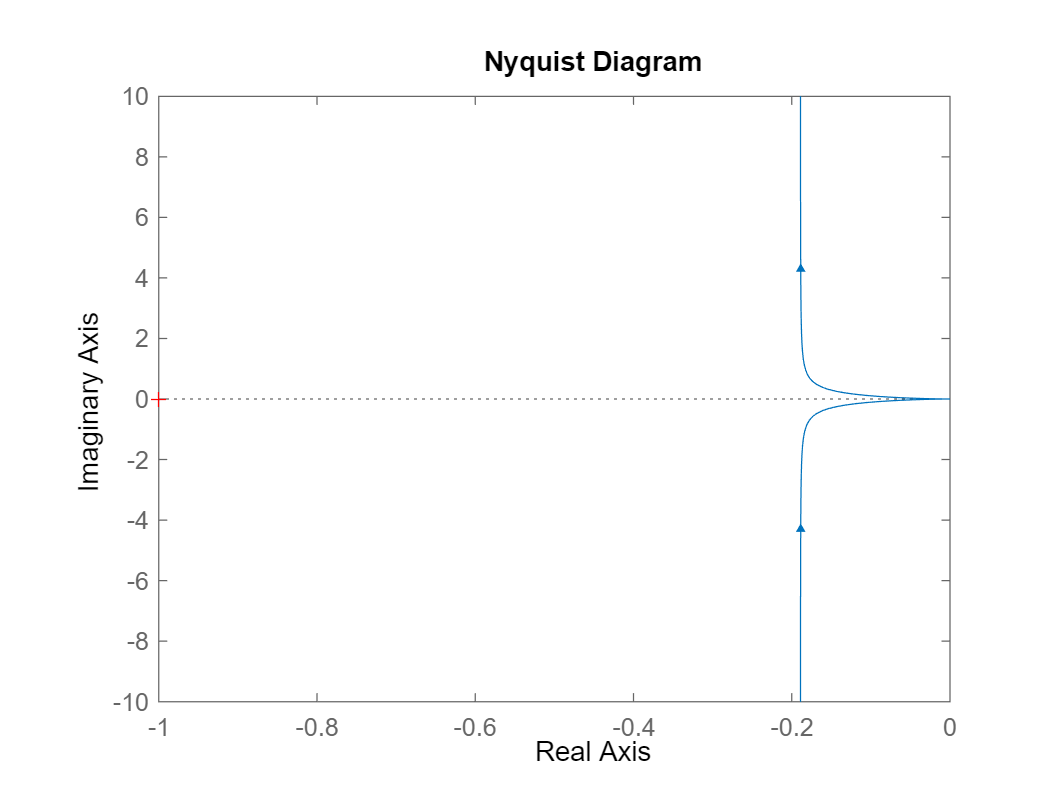

%plotting nyquist and rlocus
figure()
nyquist(G6l)

Nyqiost plot shows that the plot crosses unit citrcle at frequency of 1.86 rad/s, giving phase margin 79.5 deg. 

For phase = -pi it has 3 different gains shown on the plot below:

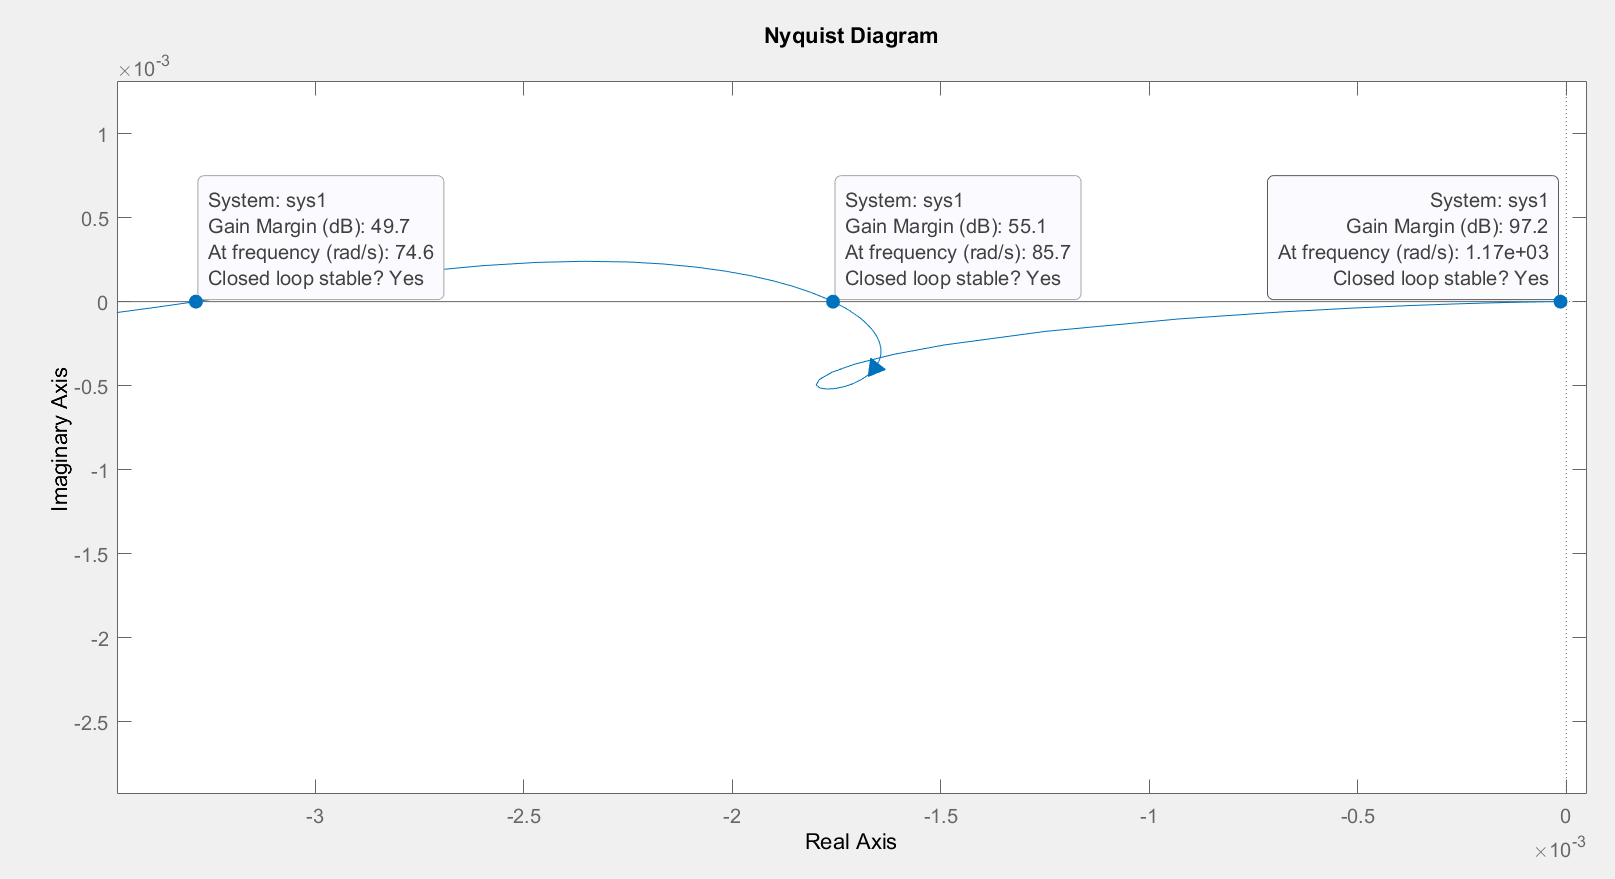

therefore the open loop system should be unstable.

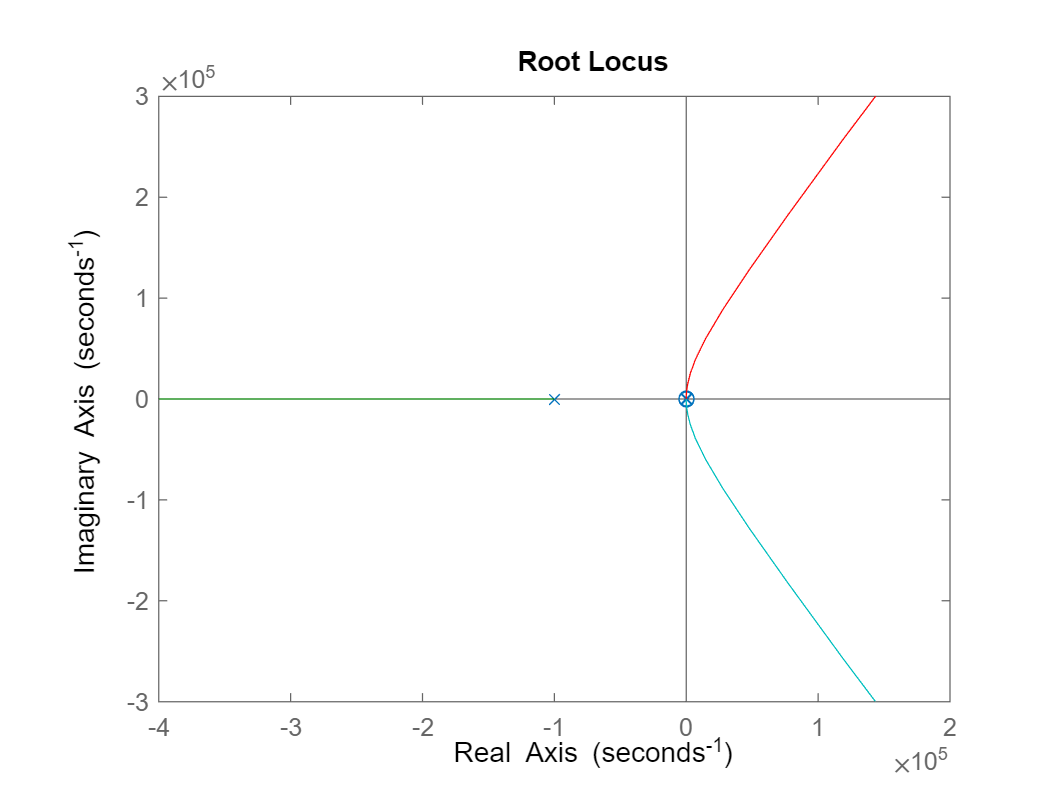

figure()
rlocus(G6l)

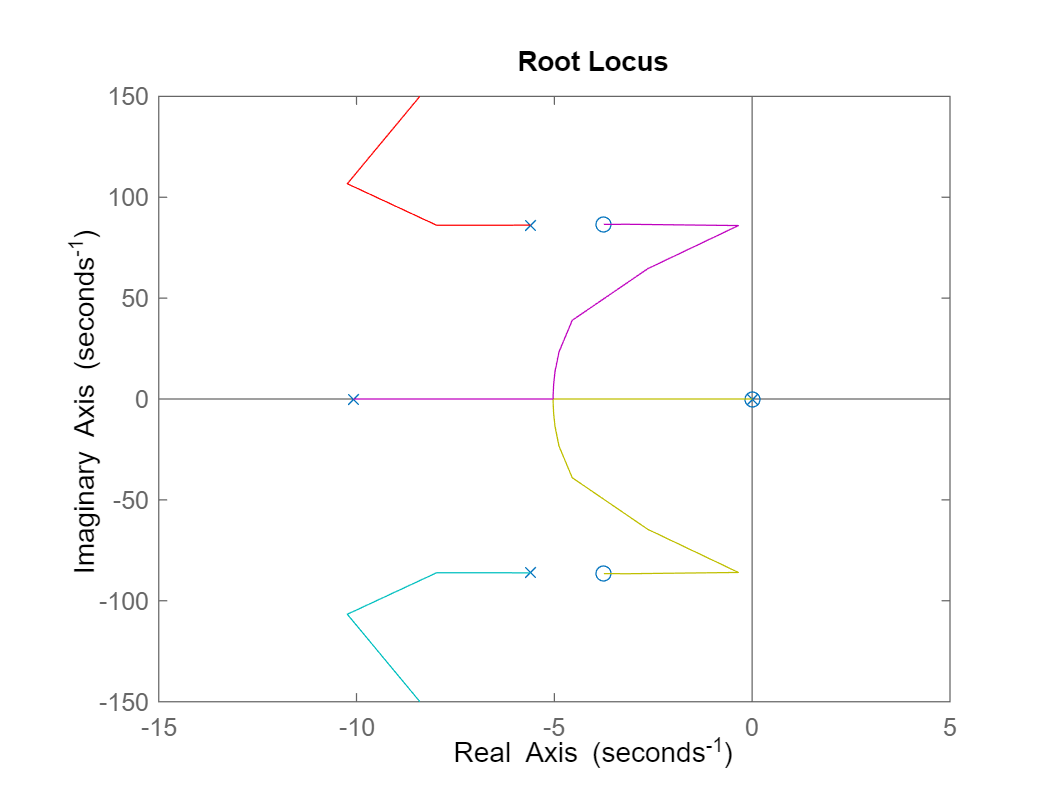

figure()
rlocus(G6l)
xlim([-15 5])
ylim([-150 150])

rlocus plot shows the existance of 5 poles and 3 zeros where one pole is insignificant due to its distance from the unit circle, while the other pole gives the system marginal stability due to its location at point (0,0). We have 3 significant poles around the unit circle to the left of the imaginary axis. 

Among the 3 zeros of the system one lies on the (0,0) point, while the other 2 are around the unit circle to the left of the imaginary axis.

This once again implies that the system is mariginally stable.

d)

%checking if variable state feedback can be designed
[Abar,Bbar,Cbar,T,k]=ctrbf(A,B,C(1,:))

Abar =    1.8605e-13  -8.6726e-13  -1.3417e-14   5.8057e-14  -4.9024e-16   3.2732e-16
    0.0015827       7.0951       2.1719   3.0011e-15   -1.212e-16   -6.884e-17
       2.3716      -3270.3      -768.84       415.22   1.4168e-15   1.8444e-16
       4.3069      -5944.3      -1397.3       755.18       2.8426   1.0347e-16
         2012       2025.6       2305.3      -1256.9      -18.017       3.5598
  -5.6569e+07   1.4563e+07  -4.7874e+07   2.6382e+07        93634       -1e+05


Bbar =   -6.5888e-15
  -6.4752e-14
   3.0875e-11
   5.6133e-11
   1.7085e-10
      5.7e+05


Cbar =       0.70711        0.183     -0.59834       0.3294            0            0


T =   -3.5355e-05      0.70711  -9.4281e-05   0.00070711  -1.1785e-09      0.70711
  -0.00035459        0.183  -0.00095531     -0.96611  -1.1941e-08     -0.18204
      0.16921     -0.59834      0.45126     -0.22664   5.6407e-06      0.59863
      0.30764       0.3294      0.82042      0.12354   1.0255e-05     -0.32939
      0.93634            0      -0.3511   3.5114e-06  -4.3888e-06            0
            0            0    -1.25e-05            0            1            0


k =      1     1     1     1     1     0


%displaying new 
poles_new = eig(Abar)

poles_new =        -1e+05 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i
      -10.077 +          0i
  -1.6665e-15 +          0i
  -2.3269e-12 +          0i


%displaying the controllable and uncontrollable poles
controllable_poles = eig(Abar(2:6,2:6))

controllable_poles =        -1e+05 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i
      -10.077 +          0i
  -2.8532e-12 +          0i


uncontrollable_poles = eig(Abar(1,1))

uncontrollable_poles =    1.8605e-13


`[Abar,Bbar,Cbar,T,k] = ctrbf(A,B,C)` decomposes the state-space system represented by `A`, `B`, and `C` into the controllability staircase form, `Abar`, `Bbar`, and `Cbar`, described above. `T` is the similarity transformation matrix and `k` is a vector of length *n*, where *n* is the order of the system represented by `A`. Each entry of `k` represents the number of controllable states factored out during each step of the transformation matrix calculation. The number of nonzero elements in `k` indicates how many iterations were necessary to calculate `T`, and `sum(k)` is the number of states in *Ac*, the controllable portion of `Abar`.

The matrix K shows us that there are 5 controllable poles and 1 uncontrollable pole. This is confirmed by calculating eigenvalues of the Abar with subtracted 1st row and 1st column. 

Matrix T is the transformation matrix such that Abar=T^-1*A*T.

The controllable system is unstable due to having a pole with positive real value.

The variable feedback controller can be designed to stabilize the system, because it has only one uncontrollable pole, which is very close to zero and is on the left side of the zero-pole plane (so it should be considered as equal to zero).

TASK4

a)

% minimal realization and pole-zero cancellation
%transfer function after performing minimal realization
G5m = minreal(G6l)

G5m =
 
                 1.9e06 s^2 + 1.425e07 s + 1.425e10
  ----------------------------------------------------------------
  s^5 + 1e05 s^4 + 2.135e06 s^3 + 7.576e08 s^2 + 7.52e09 s + 1.099
 
Continuous-time transfer function.



%poles of the system after minimal realization
poles_min = pole(G5m)

poles_min =        -1e+05 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i
      -10.077 +          0i
  -1.4611e-10 +          0i


%zeros of the system after minimal realization
zeros_min = zero(G5m)

zeros_min =       -3.7501 +     86.523i
      -3.7501 -     86.523i


b)

We have decided to remove the pole which is the least significant due to its position with regards to the imaginary axis. The greater the distance from the unit circle the smaller is its impact on the dynamic behaviour of the system.

poles_new=[0 -10.077 -5.5998+86.204i -5.5998-86.204i]

poles_new =             0 +          0i      -10.077 +          0i      -5.5998 +     86.204i      -5.5998 -     86.204i


Zeros of the system do not have to be reduced.

zeros_new=zeros_min'

zeros_new =       -3.7501 -     86.523i      -3.7501 +     86.523i


After performing the reduction we have contructed new 4th order linear system shown below.

G4s=zpk(zeros_new,poles_new,1)

G4s =
 
        (s^2 + 7.5s + 7500)
  --------------------------------
  s (s+10.08) (s^2 + 11.2s + 7462)
 
Continuous-time zero/pole/gain model.



The result is displayed in the product form.

c)

%reconstructing the state matrices A, B, C, D:
[A4, B4, C4, D4]=zp2ss(zeros_new,poles_new,1);
A4

A4 =         -11.2      -86.386            0            0
       86.386            0            0            0
      -3.6993      0.43762      -10.077            0
            0            0            1            0


B4

B4 =      1
     0
     1
     0


C4

C4 =      0     0     0     1


D4

D4 =      0


d)

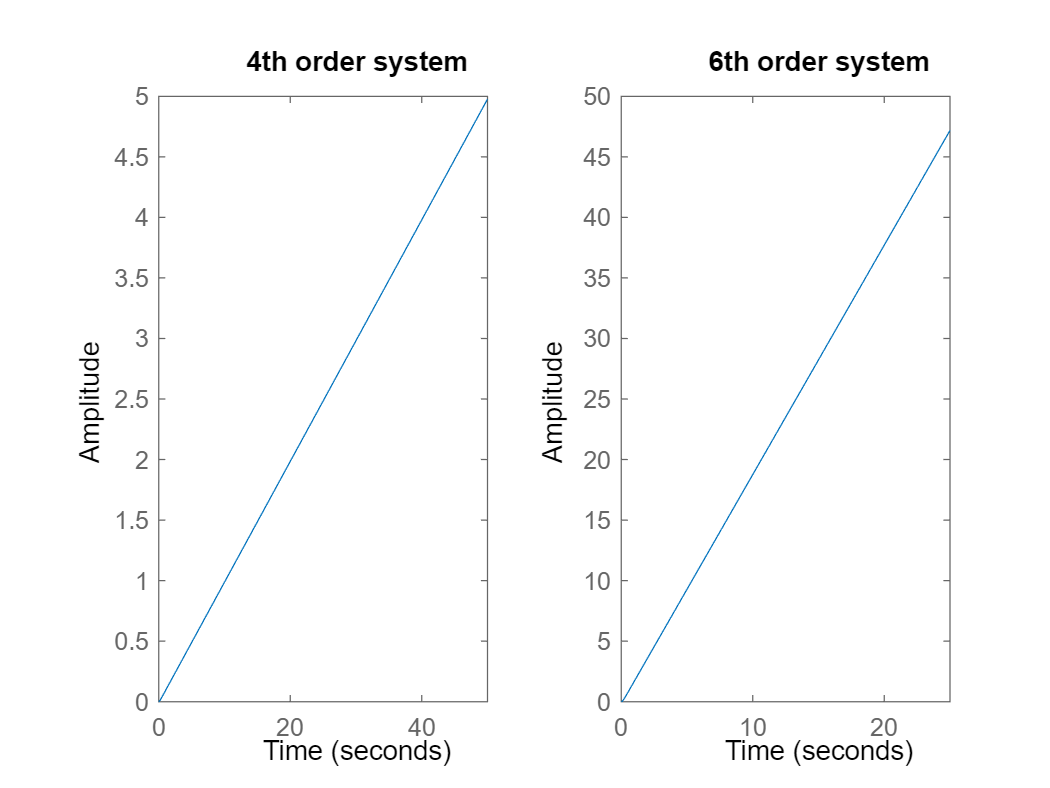

%plotting step response of the system
figure()
subplot(1,2,1)
step(G4s)
title("4th order system")
subplot(1,2,2)
step(G6l)
title("6th order system")

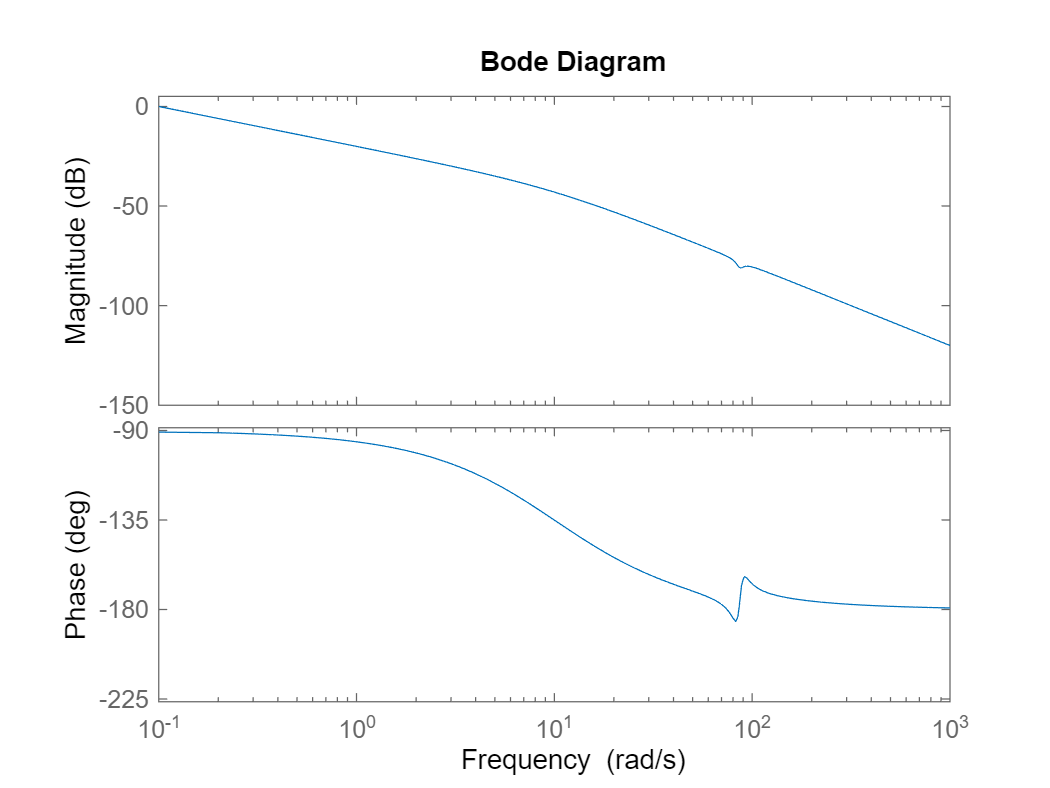

%plotting bode plot of the system
figure()
bode(G4s)

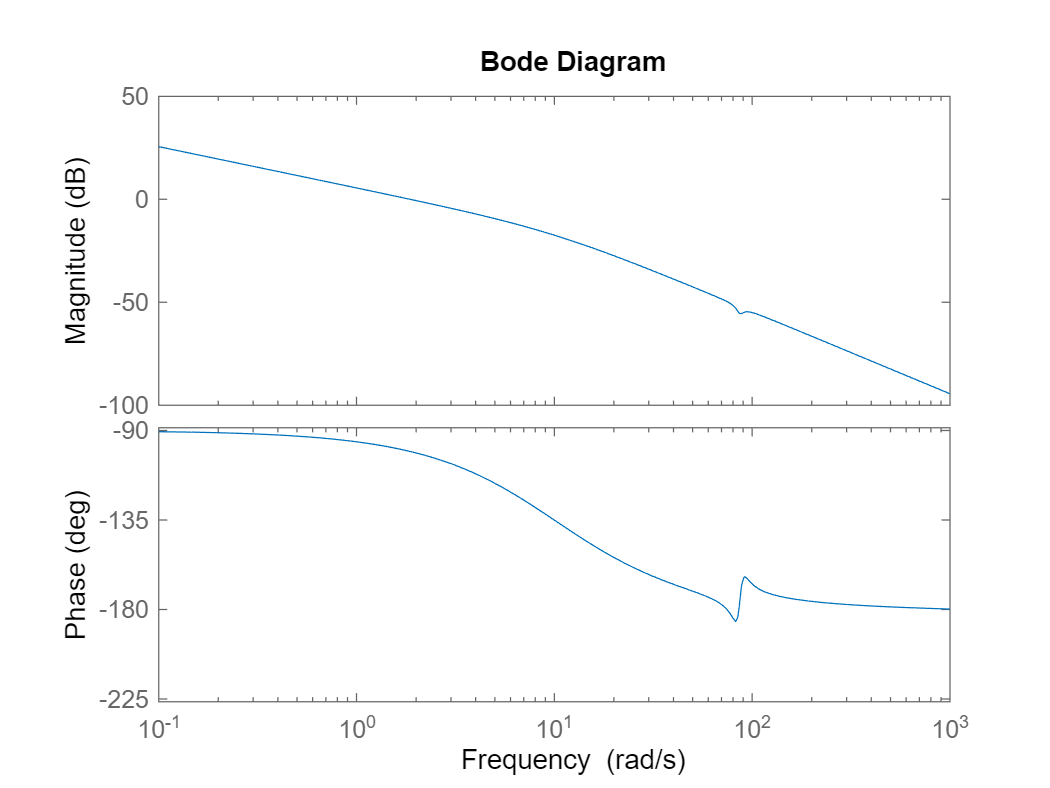

figure()
bode(G6l)

As the original system was unstabale, so is the reduced (4th order) one. The main difference is that the reduced system gain has decreased by a factor of ~10. The dynamic behaviour of the reduced system is similar to the original one which shouldn't cause any losses. This is true for both the step and bode diagram. 

TASK5

a)

% Check the controllability and observability of the system
system_order = length(A4) % equals "4"

system_order =      4


M = ctrb(A4, B4);
rank(A4)

ans =      3


rank_of_M = rank(M)  % equals "4"

rank_of_M =      4


N = obsv(A4, C4);
rank_of_N = rank(N) % equals "4"

rank_of_N =      4


So the controllability matrix has the rank of 4, while the rank of A4 = 3. This is due to the assumption that all states are available for feedback which matlab doesn't take into account.

With our assumptions we conclude that the system is fully controllable.

The same goes for observability (system is observable).

b)

damping = 0.707;
Ts=2;
OS=5;
wn=4/(damping*Ts)

wn =        2.8289


Natural frequency can be approximated using damping coefficient and settling time. 

The equation used is considered "standard" approximation, but in the more complex cases a different formula might have to be implemented to account for non linearities in the system.

% Calculate desired pole locations (which are the 2 dominant poles of the
% system)
p1 = -damping * wn + 1i * wn * sqrt(1 - damping^2);
p2 = -damping * wn - 1i * wn * sqrt(1 - damping^2);
% For a fourth-order system, repeat the steps for the second set of poles
p3 = 10*p1;  %p3&p4 have to be at least 10 times bigger than the dominant poles
p4 = 10*p2;
% Define desired pole locations
desired_poles = [p1; p2; p3; p4];
% Calculate control gains
K = acker(A4, B4, desired_poles);
% Apply state feedback controller
sys_with_controller = ss(A4 - B4*K, B4, C4, D4);
% Verify the closed-loop system poles
closed_loop_poles=eig(A4 - B4*K)

closed_loop_poles =           -20 +     20.006i
          -20 -     20.006i
           -2 +     2.0006i
           -2 -     2.0006i


eig(A4)

ans =             0 +          0i
      -10.077 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i


disp("Control Gains (K):");

Control Gains (K):


disp(K);

       23.094      -79.155     -0.37057      0.85382



disp("Closed-loop System Poles:");

Closed-loop System Poles:


disp(closed_loop_poles);

          -20 +     20.006i
          -20 -     20.006i
           -2 +     2.0006i
           -2 -     2.0006i



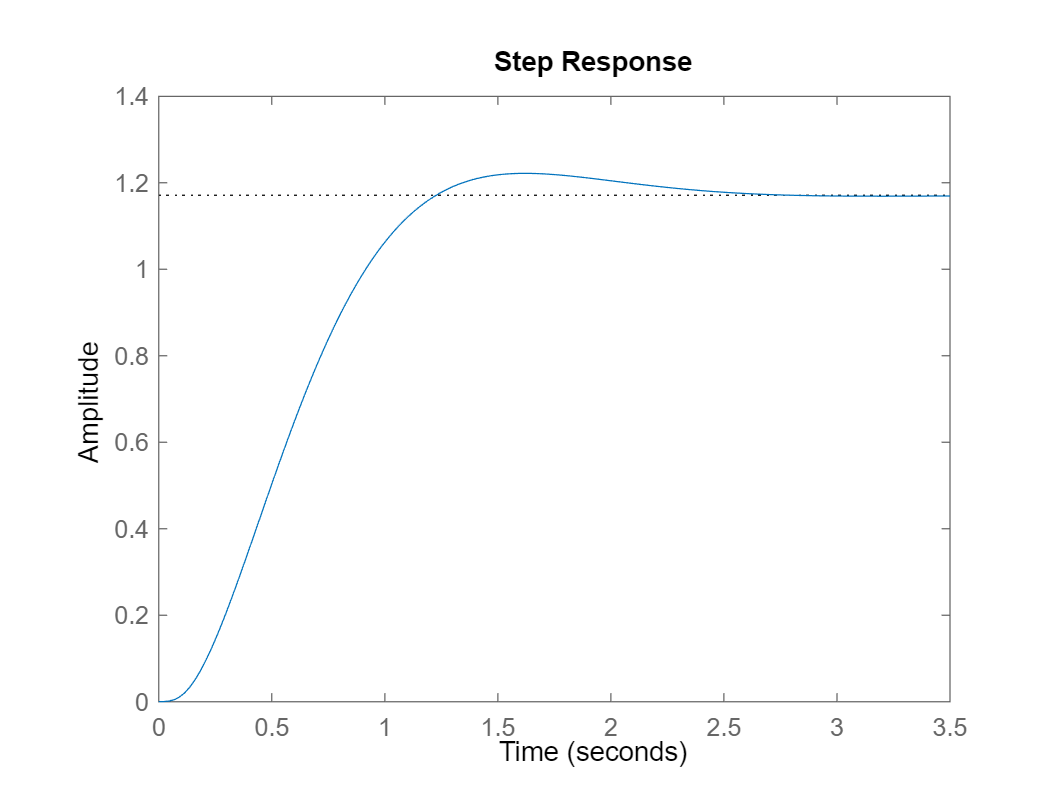


step(sys_with_controller)

stepinfo(sys_with_controller)

ans = struct with fields:
         RiseTime: 0.75955
    TransientTime: 2.1571
     SettlingTime: 2.1571
      SettlingMin: 1.0561
      SettlingMax: 1.2218
        Overshoot: 4.3229
       Undershoot: 0
             Peak: 1.2218
         PeakTime: 1.6118


The overshoot is within the specifications, but the settling time is slightly over 2s. We will now adjust the gains to meet the required criteria.

%new gain matrix
K_new=[14.0939679717973	-79.1554023636424	-0.370567971797259	0.853815822485086]

K_new =        14.094      -79.155     -0.37057      0.85382


% Apply state feedback controller
sys_with_controller_new = ss(A4 - B4*K_new, B4, C4, D4);
% Verify the closed-loop system poles
closed_loop_poles_new=eig(A4 - B4*K_new)

closed_loop_poles_new =       -15.281 +     22.353i
      -15.281 -     22.353i
      -2.2192 +     1.9518i
      -2.2192 -     1.9518i


eig(A4)

ans =             0 +          0i
      -10.077 +          0i
      -5.5998 +     86.204i
      -5.5998 -     86.204i


disp("Control Gains (K):");

Control Gains (K):


disp(K);

       23.094      -79.155     -0.37057      0.85382



disp("Closed-loop System Poles:");

Closed-loop System Poles:


disp(closed_loop_poles_new);

      -15.281 +     22.353i
      -15.281 -     22.353i
      -2.2192 +     1.9518i
      -2.2192 -     1.9518i



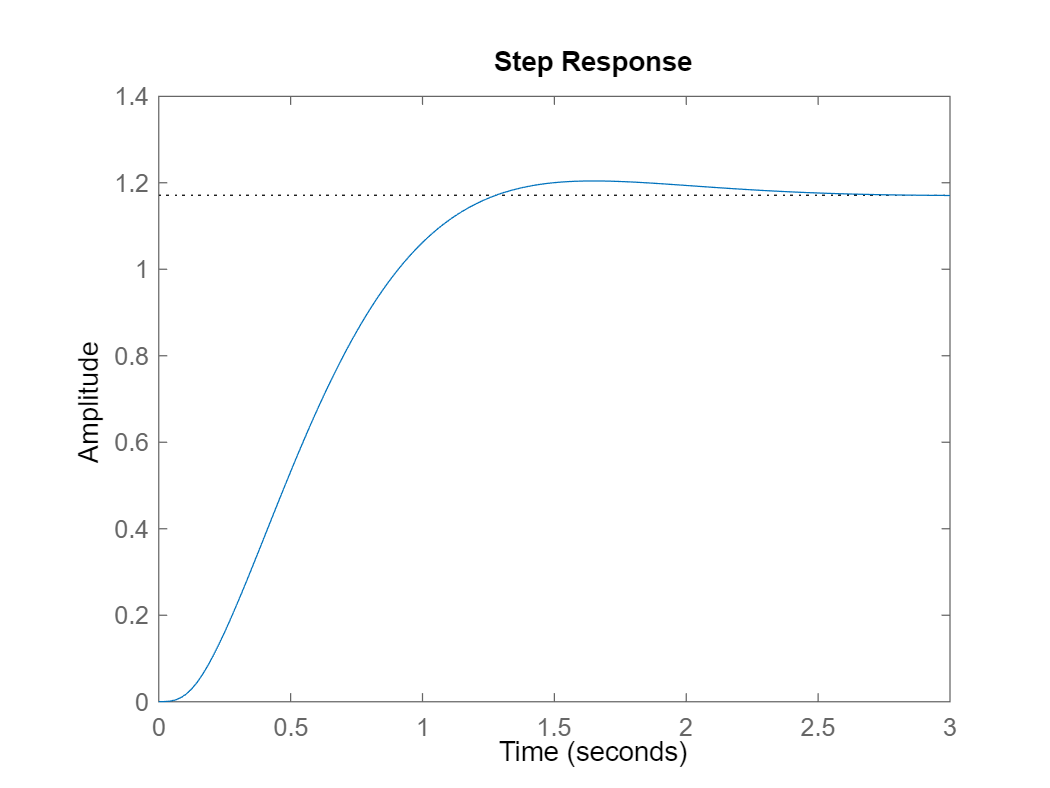


step(sys_with_controller_new)

stepinfo(sys_with_controller_new)

ans = struct with fields:
         RiseTime: 0.7717
    TransientTime: 1.9815
     SettlingTime: 1.9815
      SettlingMin: 1.0597
      SettlingMax: 1.2043
        Overshoot: 2.8217
       Undershoot: 0
             Peak: 1.2043
         PeakTime: 1.6394


After some tuning, we have adjusted the controller such that the system now has Settling time of 1.98s and Overshoot of 2.82%.

K_new

K_new =        14.094      -79.155     -0.37057      0.85382


This is the gain vector of the tuned controller.

c)

Ae = [A4 zeros(size(A4(:,1))); C4 zeros(size(C4(:,1)))];% Ae = [A4 0; C4 0]
Be = [B4; zeros(size(B4(1,:)))];% Be = [B4; 0]
Ce = [C4 zeros(size(C4(:,1)))];% Ce = [C4 0]
De = [0];
%now system is 5x5 due to integral element
system_order = length(Ae)

system_order =      5


M = ctrb(Ae, Be);
rank_of_M = rank(M)

rank_of_M =      5


N = obsv(Ae, Ce);
rank_of_N = rank(N)

rank_of_N =      4


[num2,den2] = ord2(wn, damping);
dominant = roots(den2); % dominant complex pole pair

desiredpoles_ext = [dominant' 10*conj(dominant(1)) 20*conj(dominant(2)) 40*min(dominant)];

K_e = acker(Ae, Be, desiredpoles_ext)

K_e =        110.97      -3.3451       11.755       76.685       136.61


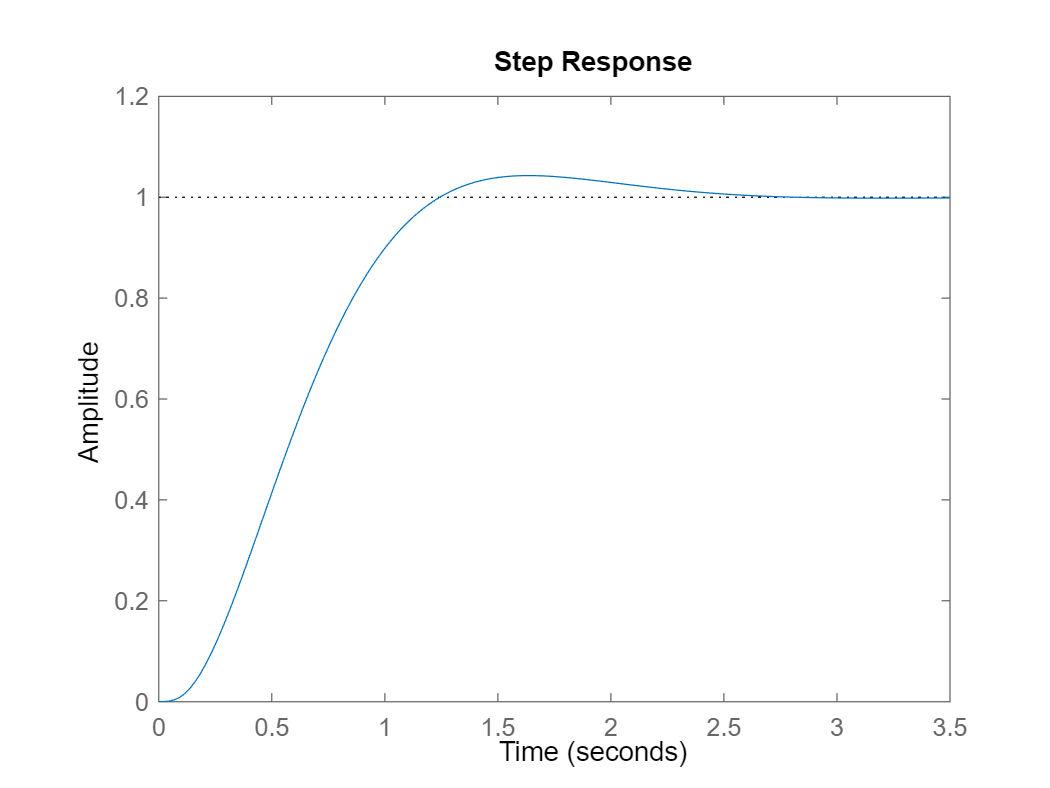

Asf_ext = Ae - Be * K_e;
[numsf_ext, densf_ext] = ss2tf(Asf_ext,  [0; 0; 0; 0; -1], Ce, De);
SYS_ext = tf(numsf_ext, densf_ext);
step(SYS_ext)

stepinfo(SYS_ext)

ans = struct with fields:
         RiseTime: 0.7661
    TransientTime: 2.1702
     SettlingTime: 2.1702
      SettlingMin: 0.90637
      SettlingMax: 1.0429
        Overshoot: 4.2882
       Undershoot: 0
             Peak: 1.0429
         PeakTime: 1.6348


Once again the settling time has to be adjusted

%new gain matrix
K_e_new=[110.968452424576	-5.34514841462968...

K_e_new =        110.97      -5.3451       8.7549       76.685       136.61


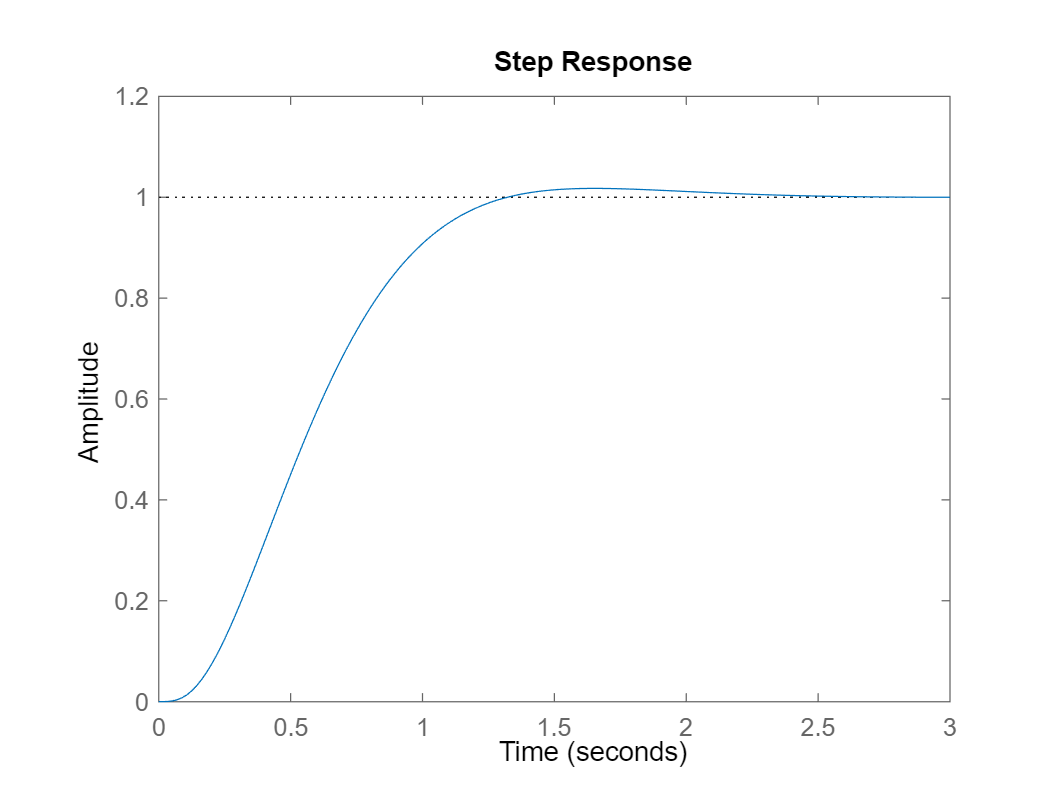

    8.7549475754236	76.6851540744224	136.610531597614]
% Apply state feedback controller
Asf_ext = Ae - Be * K_e_new;
[numsf_ext, densf_ext] = ss2tf(Asf_ext,  [0; 0; 0; 0; -1], Ce, De);
SYS_ext = tf(numsf_ext, densf_ext);
step(SYS_ext)

stepinfo(SYS_ext)

ans = struct with fields:
         RiseTime: 0.75667
    TransientTime: 1.2096
     SettlingTime: 1.2096
      SettlingMin: 0.90009
      SettlingMax: 1.0175
        Overshoot: 1.7462
       Undershoot: 0
             Peak: 1.0175
         PeakTime: 1.6455


After adjusting the gain matrix shown above, we have obtained the system with integral element which satisfies all 4 conditions imposed (ess=0, Ts<2 & OS<5%).

TASK6

%Gains of the PID controller from the table
Kp = 2.7*wn^3;
Ki = wn^4;
Kd = 3.4*wn^2 - 12;
num_cont=[Kd Kp Ki]

num_cont =        15.208       61.122       64.039


den_cont=[1 0]

den_cont =      1     0


Gc = tf(num_cont,den_cont)

Gc =
 
  15.21 s^2 + 61.12 s + 64.04
  ---------------------------
               s
 
Continuous-time transfer function.



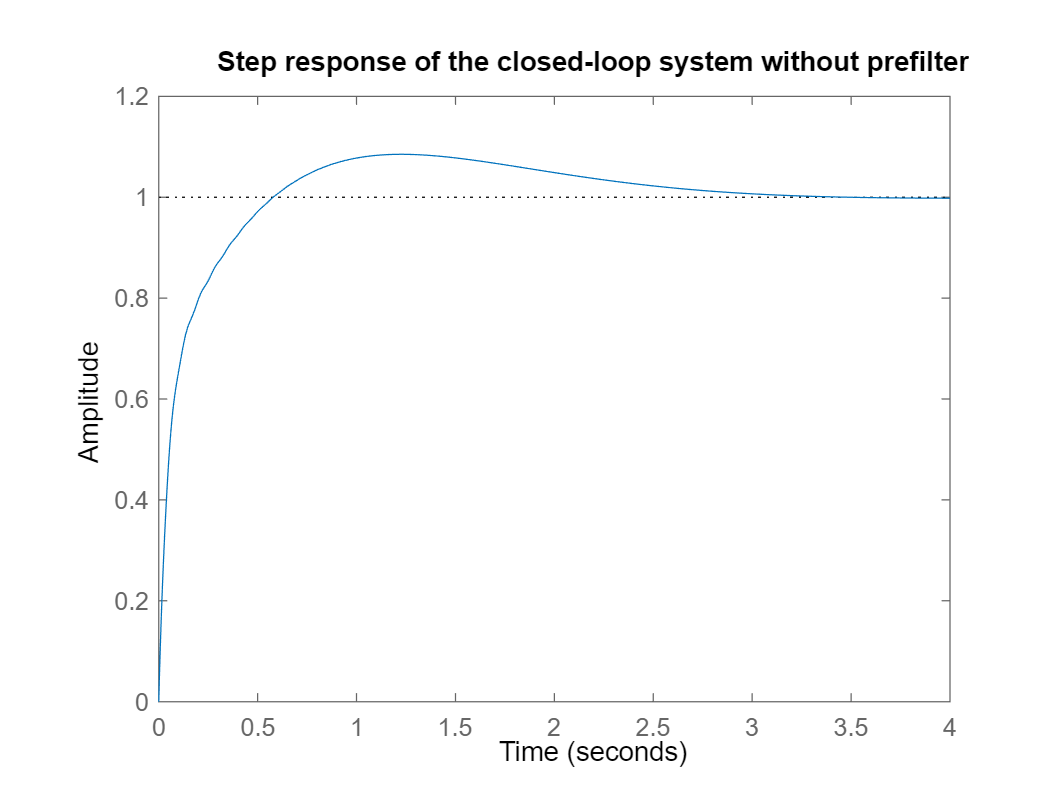

T1 = feedback(Gc*G4s,1);
figure();
step(T1);
title('Step response of the closed-loop system without prefilter');

The introduction of the PID controller using Ziegler-Nichols method allowed us to obtain a step response with 0 steady state error, but unsatisfied remaining conditions.

We will now add a prefilter which will allow the PID controller to properly satisfy all the critieria.

%creating prefeilter
num_pre=Ki;
den_pre=[Kd Kp Ki]

den_pre =        15.208       61.122       64.039


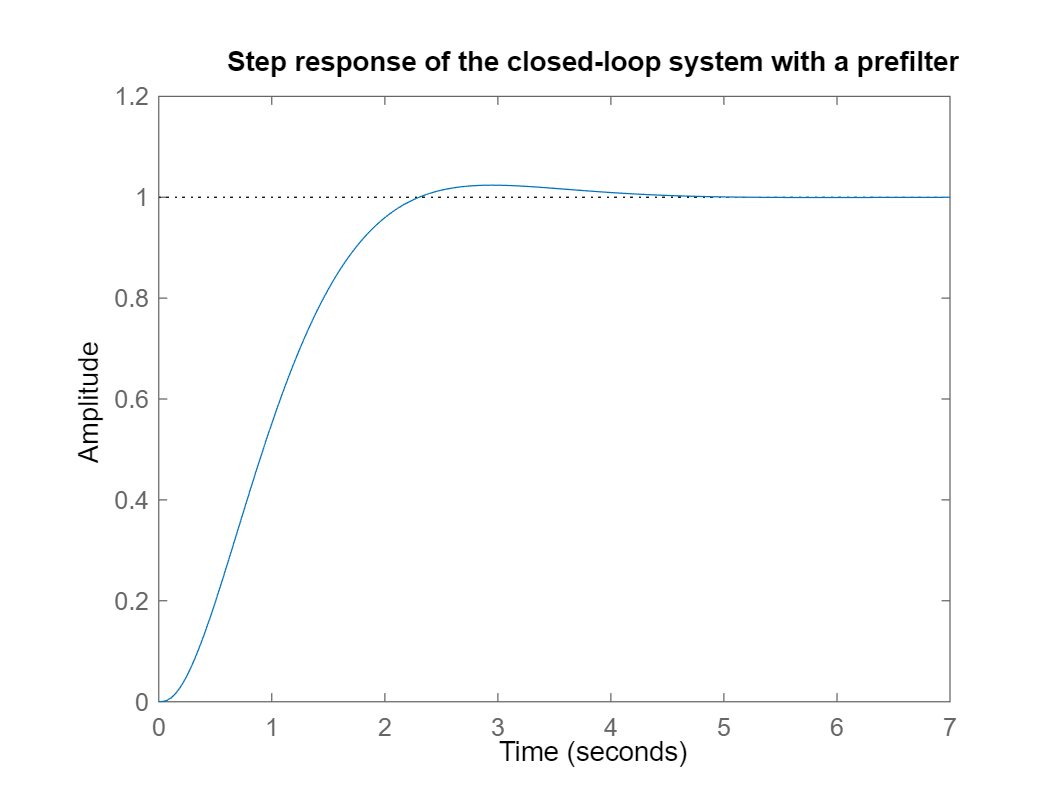

Gp=tf(num_pre, den_pre);
T1 = feedback(Gc*G4s,1);
T = T1*Gp;
figure()
step(T);
title('Step response of the closed-loop system with a prefilter')

stepinfo(T)

ans = struct with fields:
         RiseTime: 1.3962
    TransientTime: 3.352
     SettlingTime: 3.352
      SettlingMin: 0.90367
      SettlingMax: 1.0238
        Overshoot: 2.3835
       Undershoot: 0
             Peak: 1.0238
         PeakTime: 2.936


% Tuning

Now we proceed with PID tuning using a random permutation test bench, iterating through random values of Kp, Kd and Ki in a given range until all conditions are satified or code iteration limit.


% condition = false;
% iterator=0;
% while condition==false
% 
% %Gains of the PID controller from the table
% Kp = 2.7*wn^3;
% Kp=Kp+0.5*Kp*(0.5-rand(1));
% Ki = wn^4;
% Ki=Ki+0.5*Ki*(0.5-rand(1));
% Kd = 3.4*wn^2 - 12;
% Kd=Kd+0.5*Kd*(0.5-rand(1));
% num_cont=[Kd Kp Ki];
% den_cont=[1 0];
% Gc = tf(num_cont,den_cont);
% T1 = feedback(Gc*G4s,1);
% 
% 
% num_pre=[Ki];
% den_pre=[Kd Kp Ki];
% Gp=tf(num_pre, den_pre);
% T1 = feedback(Gc*G4s,1);
% T = T1*Gp;
% 
% data=stepinfo(T);
% Ov=data.Overshoot;
% ST=data.SettlingTime;
% 
% if Ov<=5 && ST <=2
%     condition=true;
% end
% 
% iterator=iterator+1;
% 
% if iterator==1000
%     condition=true;
% end
% end

From code above we obtain:

Kp=63.255

Kp =        63.255


Ki=74.131

Ki =        74.131


Kd=12.129

Kd =        12.129


Creating a new controller using these values:

num_pre=[Ki];
den_pre=[Kd Kp Ki]

den_pre =        12.129       63.255       74.131


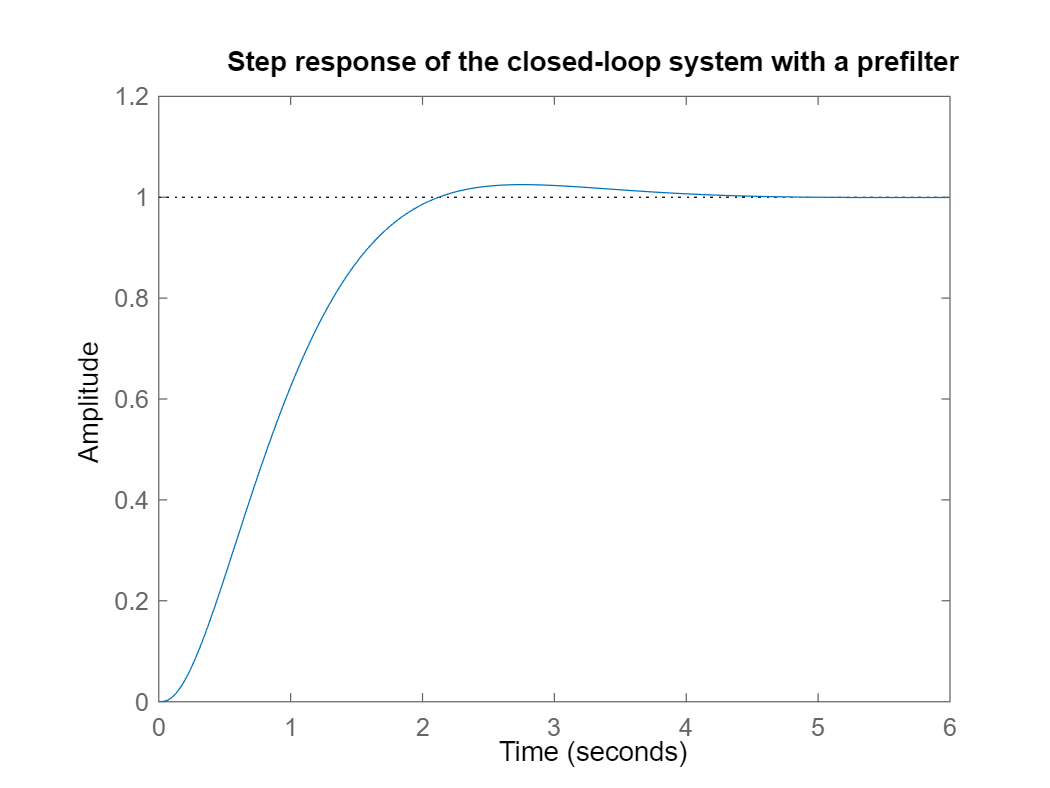

Gp=tf(num_pre, den_pre);
T1 = feedback(Gc*G4s,1);
T = T1*Gp;
figure()
step(T);
title('Step response of the closed-loop system with a prefilter')

stepinfo(T)

ans = struct with fields:
         RiseTime: 1.29
    TransientTime: 3.2079
     SettlingTime: 3.2079
      SettlingMin: 0.90523
      SettlingMax: 1.025
        Overshoot: 2.4957
       Undershoot: 0
             Peak: 1.025
         PeakTime: 2.7603


After adjusting the PID coefficiens our system meets all the conditions. In order to get it to function properly we had to create an initial PID controller and equip it with appropriate prefilter resultion in a correct solution.